## Wing Design

clear
Set default figure size (in inches)
set(groot, 'defaultFigureUnits', 'inches');
set(groot, 'defaultFigurePosition', [1, 1, 6, 4]); % Width = 6 inches, Height = 4 inches

% Set default font settings for all text in plots
set(groot, 'defaultAxesFontName', 'Times New Roman');
set(groot, 'defaultAxesFontSize', 12); % Font size for axis labels and ticks
set(groot, 'defaultTextFontSize', 12); % Font size for text in the plot
set(groot, 'defaultAxesTitleFontSizeMultiplier', 1.2); % Slightly larger title
set(groot, 'defaultLegendFontSize', 11); % Font size for legend text

% Set default line and marker settings
set(groot, 'defaultLineLineWidth', 1.5); % Default line width
set(groot, 'defaultLineMarkerSize', 8); % Default marker size

% Set default box and grid
set(groot, 'defaultAxesBox', 'on'); % Enable box around plots by default
set(groot, 'defaultAxesGridLineStyle', '-'); % Solid grid lines
set(groot, 'defaultAxesXGrid', 'on'); % Enable grid for X axis
set(groot, 'defaultAxesYGrid', 'on'); % Enable grid for Y axis

## 1.Design CL

CLdesC1 = 0.4623;
CLdesC2 = 0.3008;

## 2.Airfoil Selection

1.Choose a t/c ratio optimum for the cruise speed

2.Choose a CLopt (at L/D max or called drag-bucket) close to design CL

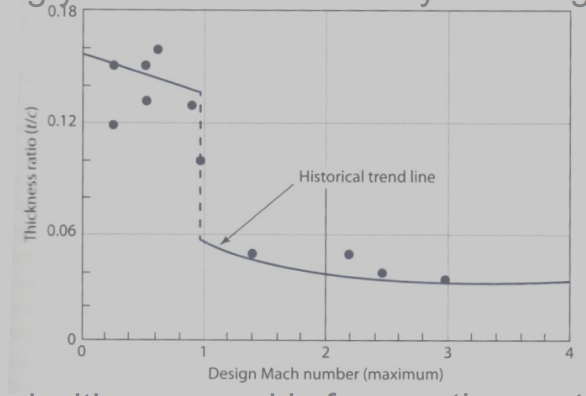

kA= 0.95;
Lambdades = 20*pi/180;
MDD = 0.85;

polarPath =  '../Airfoils/Airfoil polar data'; % Specify your directory path here
files = dir(polarPath); % Get a structure array with file information
polarNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories

XYPath =  '../Airfoils/Airfoil XY data'; % Specify your directory path here
files = dir(XYPath); % Get a structure array with file information
XYNames = {files(~[files.isdir]).name}; % Extract names of all files, excluding directories
figure(4)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    FF(i) = (1 + 0.6.*thisairfoil.t_c./thisairfoil.x_cm + 100 .*thisairfoil.t_c.^4) .* (1.34.*MDD.^0.18.*(cos(Lambdades)).^0.28);
    stallAngle(i) = thisairfoil.alphaSPos;
    CLmax(i) = max(thisairfoil.Cl);
    L_Ddes(i) = thisairfoil.L_DatCL(CLdesC1);
    t_c(i) = thisairfoil.t_c;
end

airfoilIdx = CLmax.*L_Ddes

airfoilIdx =    67.4807   68.9838   74.8436   85.4821   92.0619  107.0470  104.0407  114.4660  121.2740   53.3781  120.9334  134.6351  128.5125  102.6098  140.1716


for i = 1:length(polarNames)
    polarNames_new(i) = extractBetween(polarNames(i), 4, 10);
end
airfoilData = table(polarNames_new', FF', t_c', stallAngle'.*180/pi, CLmax', L_Ddes', airfoilIdx', 'VariableNames', {'Name', 'Skin Friction Form Factor', 't/c', 'stallAngle','Clmax', 'L/D design', 'CLmax x L/D design'})

airfoilData = 15×7 table
       Name        Skin Friction Form Factor      t/c       stallAngle    Clmax     L/D design    CLmax x L/D design
    ___________    _________________________    ________    __________    ______    __________    __________________

    {'sc20010'}              1.501               0.10003      13.75       1.2817      52.649            67.481      
    {'sc20012'}             1.5566               0.12003      15.25       1.3893      49.654            68.984      
    {'sc20410'}             1.3218              0.020035      12.75       1.4554      51.425            74.844      
    {'sc20412'}             1.3457              0.030129      15.25       1.6283      52.498            85.482      
    {'sc20414'}             1.3679

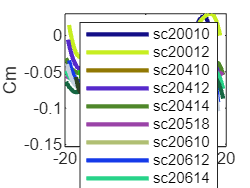

figure(7)
clf;
for i = 1:length(polarNames)
    thisairfoil = Airfoil();
    polarName = polarNames(i);
    shapeName = XYNames(i);
    thisairfoil = thisairfoil.readPolar(string(fullfile(polarPath, polarName)));
    thisairfoil = thisairfoil.readShape(string(fullfile(XYPath, shapeName)));
    thisairfoil = thisairfoil.interpShape(9);
    randomColor = rand(1, 3); % Generate a random RGB color
    plot(thisairfoil.alpha.*180/pi,thisairfoil.Cm,'LineWidth',2, 'Color', randomColor)
    hold on
end
legend(polarNames_new)
xlabel("alpha (degrees)")
ylabel("Cm")

### Conclusion:

polarName = "xf-sc20714-il-1000000.csv";
shapeName = "sc20714.dat.txt";
airfoil = Airfoil();
airfoil = airfoil.readPolar(string(fullfile(polarPath, polarName)));
airfoil = airfoil.readShape(string(fullfile(XYPath, shapeName)));
airfoil = airfoil.interpShape(9);

## 3.Shape

1.Use MDO to get best geometry

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = "    "18.5768"

    "Fuel fraction: "    "0.41439"

    "Wing Mass [kg]= "    "37350.6993"

    "Total Mass [kg] = "    "418159.7866"

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = "    "18.5768"

    "Fuel fraction: "    "0.41439"

    "Wing Mass [kg]= "    "37350.6994"

    "Total Mass [kg] = "    "418159.7867"

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = "    "18.5768"

    "Fuel fraction: "    "0.41439"

    "Wing Mass [kg]= "    "37350.6994"

    "Total Mass [kg] = "    "418159.787"

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = "    "18.5768"

    "Fuel fraction: "    "0.41439"

    "Wing Mass [kg]= "    "37350.6994"

    "Total Mass [kg] = "    "418159.7866"

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = "    "18.5768"

    "Fuel fraction: "    "0.41439"

    "Wing Mass [kg]= "    "37350.6997"

    "Total Mass [kg] = "    "418159.7874"

    "L/D cruise 1 = "    "18.16"

    "L/D cruise 2 = " 

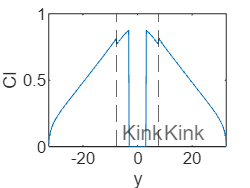

wing_opt_mod =   WingGeometry with properties:

             cr: 14.2862
             ck: 10.8422
             ct: 3.5000
              s: 32.5000
             yk: 7.6560
     Lambdain50: 0.2212
    Lambdaout50: 0.4267
              N: 301
             Sc: [0.3792 0.7722 0.7861 0.8000 0.8138 0.8277 0.8416 0.8554 0.8693 0.8832 0.8971 0.9109 0.9248 0.9387 0.9526 0.9664 0.9803 0.9942 1.0081 1.0219 1.0358 1.0497 1.0636 1.0774 1.0913 1.1052 1.1190 1.1329 1.1468 1.1607 1.1745 … ] (1×301 double)
         stripy: [-32.5000 -32.2833 -32.0667 -31.8500 -31.6333 -31.4167 -31.2000 -30.9833 -30.7667 -30.5500 -30.3333 -30.1167 -29.9000 -29.6833 -29.4667 -29.2500 -29.0333 -28.8167 -28.6000 -28.3833 -28.1667 -27.9500 -27.7333 -27.5167 … ] (1×301 double)
             AR: 7.7000
            Sin: 192.3830
           Sout: 356.3170
           cbar: 9.8676
              b: 65
           SREF: 548.7000
      twist_max: 0.0817
           

wing_opt_mod =   WingGeometry with properties:

             cr: 14.2862
             ck: 10.8422
             ct: 3.5000
              s: 32.5000
             yk: 7.6560
     Lambdain50: 0.2212
    Lambdaout50: 0.4267
              N: 301
             Sc: [0.3792 0.7722 0.7861 0.8000 0.8138 0.8277 0.8416 0.8554 0.8693 0.8832 0.8971 0.9109 0.9248 0.9387 0.9526 0.9664 0.9803 0.9942 1.0081 1.0219 1.0358 1.0497 1.0636 1.0774 1.0913 1.1052 1.1190 1.1329 1.1468 1.1607 1.1745 … ] (1×301 double)
         stripy: [-32.5000 -32.2833 -32.0667 -31.8500 -31.6333 -31.4167 -31.2000 -30.9833 -30.7667 -30.5500 -30.3333 -30.1167 -29.9000 -29.6833 -29.4667 -29.2500 -29.0333 -28.8167 -28.6000 -28.3833 -28.1667 -27.9500 -27.7333 -27.5167 … ] (1×301 double)
             AR: 7.7000
            Sin: 192.3830
           Sout: 356.3170
           cbar: 9.8676
              b: 65
           SREF: 548.7000
      twist_max: 0.0817
           

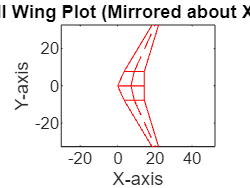

run("runWingMDO.m")

## 4.Dihedral

-G17 presents a quantitative estimate

## 5.Aero Analysis

-Wing stall angle is the angle when any section reaches stall

Lifting Curve Slope:

    "Stall at alpha = "    "11.6667"

    "Stall position y = "    "-5.85"

    "alpha_e"    "15.5069"



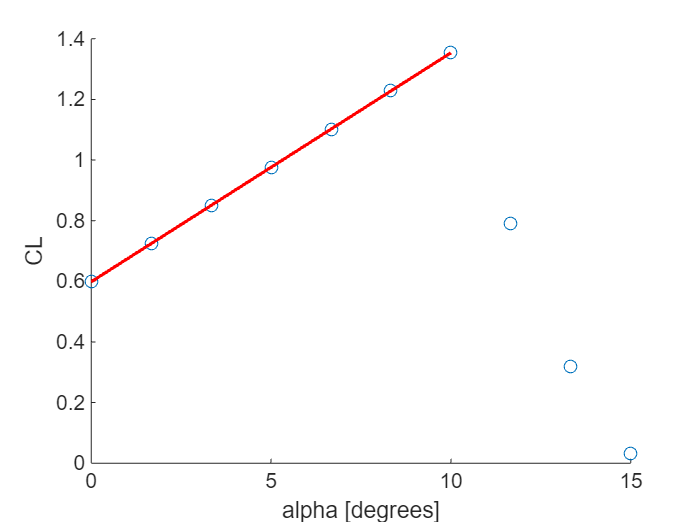

%1. cruise1:
load("wing_opt.mat")
load("airfoil.mat")
[a_c1, b_c1,CLmax_c1] = wingLiftCurveSlope(wing_opt,airfoil,cruise1.h,cruise1.M,0,15*pi/180,10,true,false);

    "Stall at alpha = "    "11.5862"

    "Stall position y = "    "-5.2"

    "alpha_e"    "15.5196"



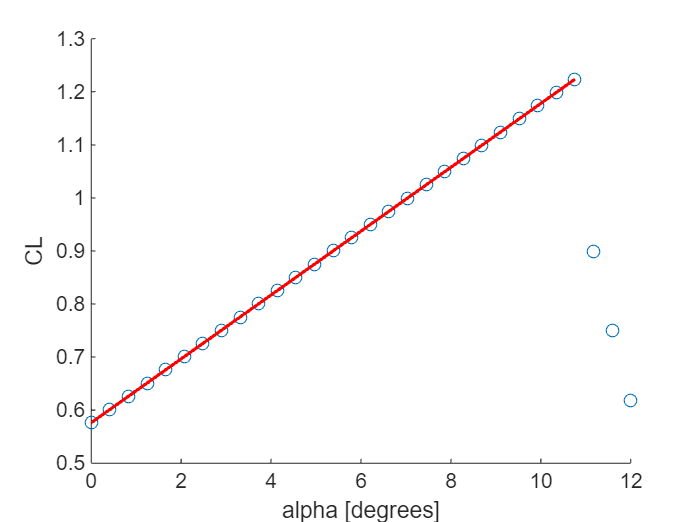


%2. Landing
[a_L, b_L,CLmax_clean_L] = wingLiftCurveSlope(wing_opt,airfoil,0.0,0.2,0,12*pi/180,30,true,false);

## 6.Aileron

Raymer:

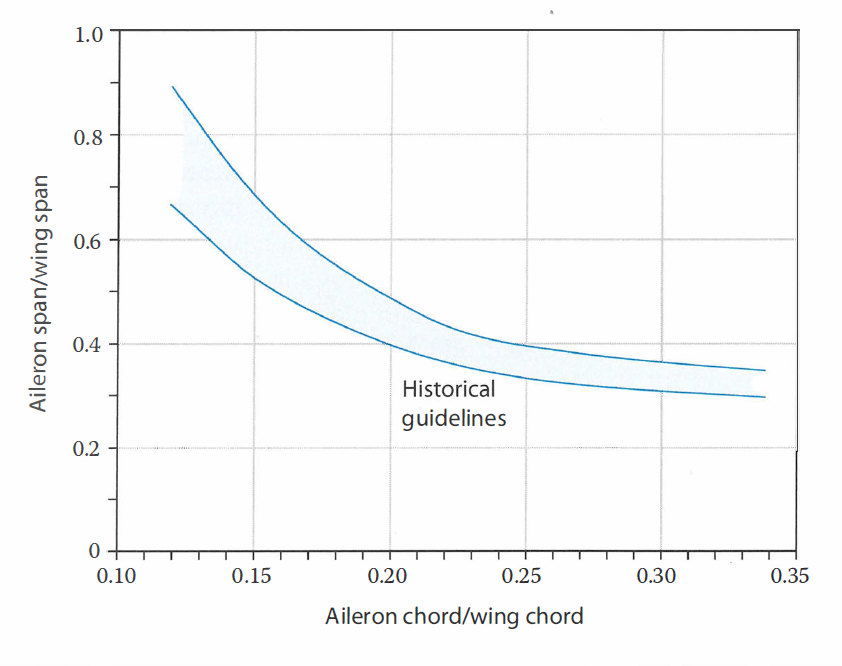

Extend from 50% span to 90% span, from graph y=0.35, x=0.25

## 7.HLD

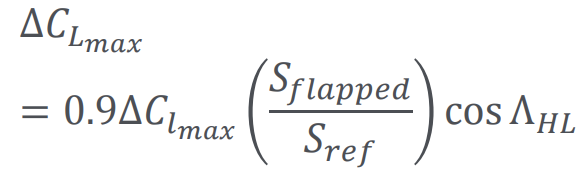

1.Calculate CLmax requirement at landing and takeoff

2.Select

load("wing_opt.mat")
run("SetParametersMDO.m")

CLmax_L_des = 2.69;

slot = controlSurface();
slot.y_s = bodyDiameter/2/wing_opt.s;
slot.dy_s = (wing_opt.yk-bodyDiameter/2)/wing_opt.s;
slot.w_c = 0.3;
slot.color = 'r';
slot.location = 'TE';
slot.HLDtype = 'DoubleSlotted';
slot.cf_c = 1.3;
slot = slot.calcS(wing_opt)

slot =   controlSurface with properties:

         y_s: 0.0982
        dy_s: 0.1374
         w_c: 0.3000
       color: 'r'
     HLDtype: 'DoubleSlotted'
        area: 31.7436
    LambdaHL: 0
    location: 'TE'
        cf_c: 1.3000
      dClmax: []


slot = slot.calcClInc();

flap = controlSurface(); 
flap.y_s = 0.26;
flap.dy_s = 0.31;
flap.w_c = 0.3;
flap.color = 'r';
flap.location = 'TE';
flap.HLDtype = 'Fowler';
flap.cf_c = 1.3;
flap = flap.calcS(wing_opt)

flap =   controlSurface with properties:

         y_s: 0.2600
        dy_s: 0.3100
         w_c: 0.3000
       color: 'r'
     HLDtype: 'Fowler'
        area: 55.1256
    LambdaHL: 0.2981
    location: 'TE'
        cf_c: 1.3000
      dClmax: []


flap = flap.calcClInc();

slat = controlSurface();
slat.y_s = 0.26;
slat.dy_s = 0.7;
slat.w_c = 0.2;
slat.color = 'r';
slat.location = 'LE';
slat.cf_c = 1.3;
slat.HLDtype = 'Slat';
slat = slat.calcS(wing_opt)

slat =   controlSurface with properties:

         y_s: 0.2600
        dy_s: 0.7000
         w_c: 0.2000
       color: 'r'
     HLDtype: 'Slat'
        area: 82.4248
    LambdaHL: 0.5425
    location: 'LE'
        cf_c: 1.3000
      dClmax: []


slat = slat.calcClInc();

%dClmax = [1.3*cf_c, 1.6*cf_c, 1.9*cf_c] % Fowler, Double slotted, Triple slotted
%dClmaxLE = [0.2, 0.3, 0.4*cf_c] % Fixed slotted, leading-edge flap, slat
dCLmax = 0.9/wing_opt.SREF*2*(slot.dClmax*slot.area*cos(slot.LambdaHL) + flap.dClmax*flap.area*cos(flap.LambdaHL) + slat.dClmax*slat.area*cos(slat.LambdaHL))

dCLmax = 0.6292

CLmax_L = CLmax_clean_L + dCLmax

CLmax_L = 1.8530

aileron = controlSurface();
aileron.y_s = 0.6;
aileron.dy_s = 0.35;
aileron.w_c = 0.25;
aileron.cf_c = 0.0;
aileron.location = 'TE';
aileron.color = 'g';
aileron.HLDtype = 'Aileron'

aileron =   controlSurface with properties:

         y_s: 0.6000
        dy_s: 0.3500
         w_c: 0.2500
       color: 'g'
     HLDtype: 'Aileron'
        area: []
    LambdaHL: []
    location: 'TE'
        cf_c: 0
      dClmax: []


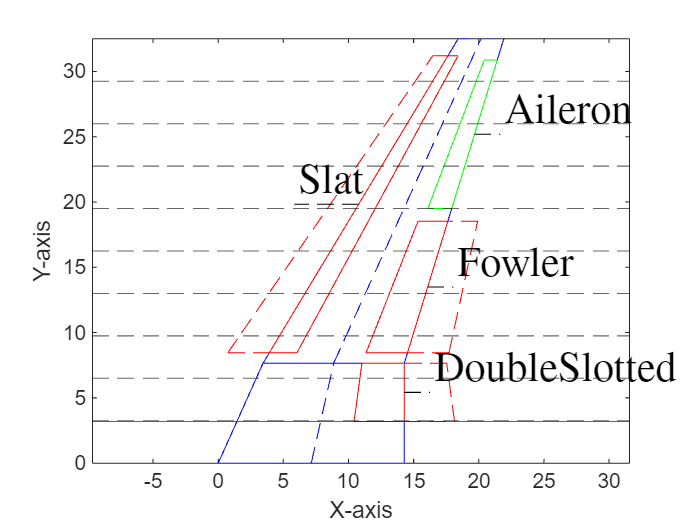

figure(4)
clf;
wing_opt.plotWing()
hold on
aileron.plotCSTE(wing_opt)
hold on
slot.plotCSTE(wing_opt)
hold on
flap.plotCSTE(wing_opt)
hold on
slat.plotCSLE(wing_opt)
hold on
yline(bodyDiameter/2)
hold on
for i = 1:10
    yline(i*wing_opt.s/10,'--')
    hold on
end
ylim([0 65/2])